# EXAMPLE: ZELDOVICH MECHANISM

It is desired to evaluate the nitric oxide (NO) emissions generated by the Zeldovich thermal mechanism in an LPP (Lean Premixed Prevaporized) gas turbine where a lean mixture of Fuel-Air is burned at constant pressure with a ratio of generic $\phi$ equivalence. The reactant mixture is compressed isentropically to enter the combustion chamber at $T = 700 \ \text{K}$ and $p = 10 \ \text{bar}$. Under these conditions, the mixture ignites, reacting adiabatically at constant pressure (HP process) until reaching the adiabatic flame temperature $T_p \left(\phi \right)$. Knowing that the average time that the mixture of products remains at the adiabatic temperature is about 10 ms, i.e., residence time $\tau = 10 \ \text{ms}$, it is requested to represent in the interval $0\ldotp 5\le \phi \le 1$:

- The mole fractions of the reactant mixture.

- The mole fractions of the product mixture. Assume incomplete combustion that takes into account the presence of H, O, and OH in the product mixture.

- The adiabatic flame temperature.

- The molar fraction of nitric oxide at the exit of the combustion chamber, $X_{\mathrm{NO}}$.

- What is the maximum value of $\phi <1$ that allows guaranteeing a molar fraction of nitric oxide less than 50 ppm?

- Finally calculate the molar fraction of nitric oxide at the combustion chamber outlet assuming that NO is also in equilibrium, $X_{\mathrm{NO},\;\mathrm{eq}}$. Suppose for this incomplete combustion taking into account the presence of H, O, OH, and NO in the mixture of products. Compare the results obtained with those of section 5 and comment on the differences observed.

**NOTE:** This script uses ["Curves Intersection" - FileExchange](https://in.mathworks.com/matlabcentral/fileexchange/22441-curve-intersections).

**@author:** Alberto Cuadra Lara

                 PhD Candidate - Group Fluid Mechanics

                 Universidad Carlos III de Madrid

Last update March 30 2022

## 1. The mole fractions of the reactant mixture

### Set fuel

Fuel = 'CH4';

### Initialize

species = {Fuel, 'CO2', 'CO2', 'CO', 'H2O', 'H2', 'O2', 'N2', 'Ar', 'O', 'OH', 'H'};
self = App(species);

Loading NASA database ... OK!
NASA short database loaded from main path ... OK!


### Set initial conditions

self = set_prop(self, 'TR', 700, 'pR', 10, 'phi', 0.4:0.01:1);
self.PD.S_Fuel     = {Fuel};
self.PD.S_Oxidizer = {'O2'};
self.PD.S_Inert    = {'N2', 'Ar', 'CO2'};
self.PD.proportion_inerts_O2 = [78.084, 0.9365, 0.0319] ./ 20.9476;

### Set additional inputs

self = set_prop(self, 'pP', self.PD.pR.value); 

### Miscellaneous

self.Misc.FLAG_RESULTS = false; % Do not print results in the command window

### Solve problems

self = SolveProblem(self, 'HP');

COMPUTING Nº MOLES FROM EQUIVALENCE RATIO (PHI).


### Get results

mix1 = self.PS.strR;
mix2 = self.PS.strP;

### Plot mole fractions of the reactant mixture

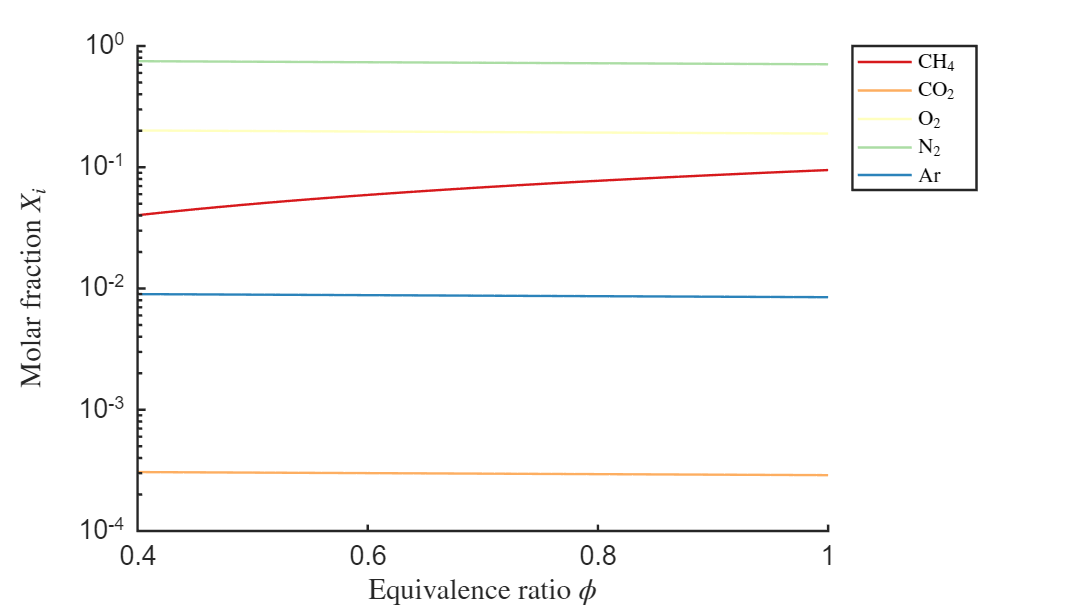

self.Misc.config.labelx = 'Equivalence ratio $\phi$';
self.Misc.config.labely = 'Molar fraction $X_i$';
displaysweepresults(self, mix1, self.PD.phi.value);

## 2. The mole fractions of the product mixture

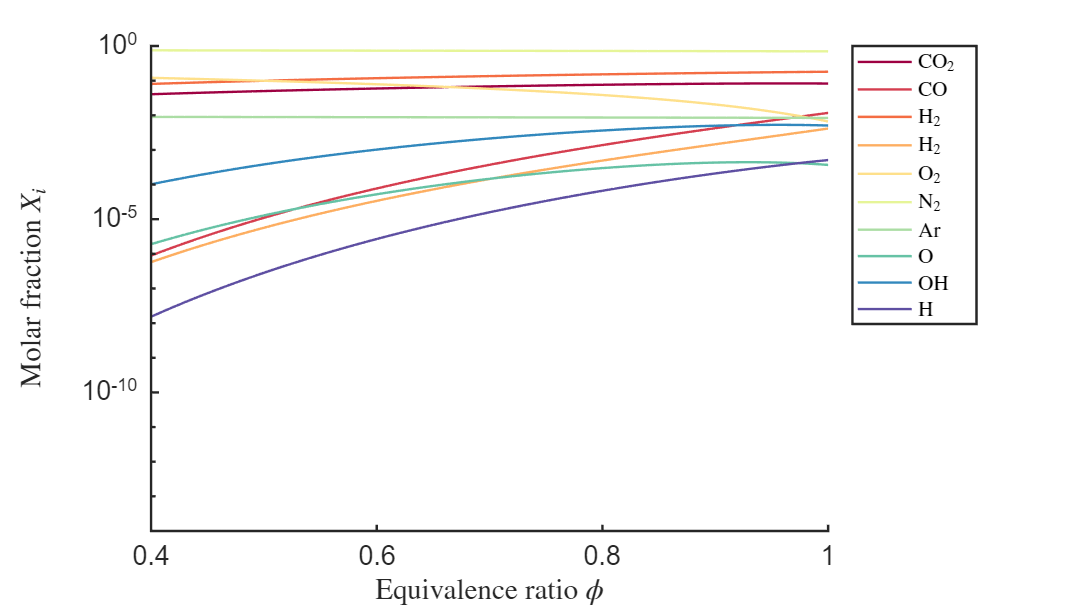

self.Misc.config.labelx = 'Equivalence ratio $\phi$';
self.Misc.config.labely = 'Molar fraction $X_i$';
displaysweepresults(self, mix2, self.PD.phi.value);

## 3. The adiabatic flame temperature

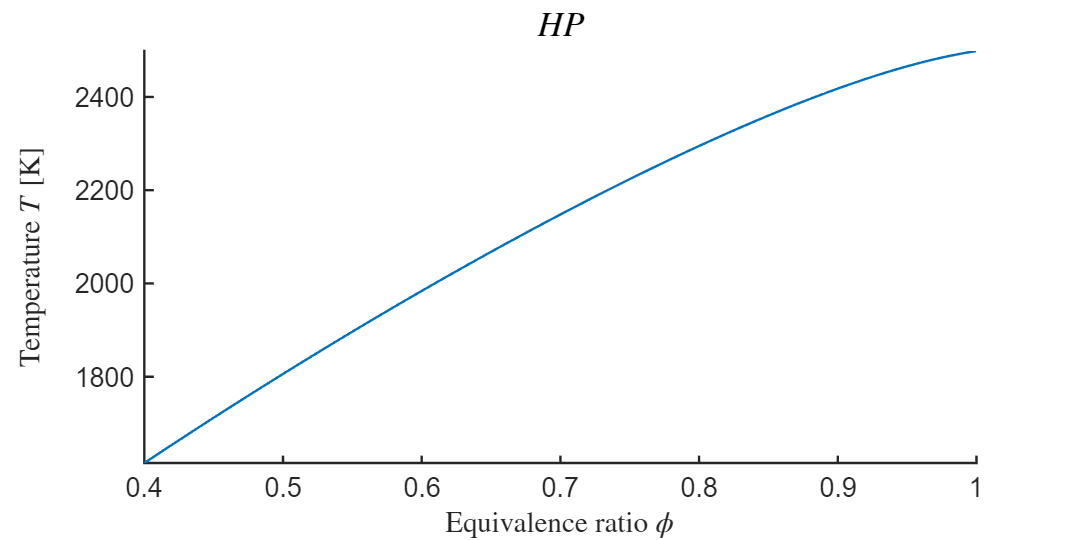

self.Misc.config.labelx = 'Equivalence ratio $\phi$';
self.Misc.config.labely = 'Temperature $T$ [K]';
self.Misc.config.tit = strrep(self.PD.ProblemType, '_', ' ');
plot_figure(self.PD.phi.value, mix2, 'phi', 'T', self.Misc.config, ...

    self.PD.CompleteOrIncomplete);

## 4. The molar fraction of nitric oxide at the exit of the combustion chamber, XNO

Compute NO using Zeldovich mechanism

tr = 10e-3;                                % Residence time [s]
R = self.C.R0;                             % Universal gas constant [J/mol K]
p = self.PD.pR.value * 1e5;                % Pressure [Pa]
T = cell2vector(mix2, 'T');                % Temperature of the products [K]
molar_fractions = cell2vector(mix2, 'Xi'); % Molar fraction of the products [-]

index_N2 = find_ind(self.S.LS, 'N2');
index_O = find_ind(self.S.LS, 'O');

X_N2 = molar_fractions(index_N2, :);
X_O_eq = molar_fractions(index_O, :);

X_NO_zeld = 3.6e8 * exp(-38610 ./ T) .* (p ./ (R * T)) .* X_O_eq .* X_N2 .* tr;

## 5. What is the maximum value of $\phi <1$ that allows guaranteeing a molar fraction of nitric oxide less than 50 ppm?

Compute intersection points (needs Curves Intersection - FileExchange)

% Set limit conditions (50 ppm of NO)
line_dashed_y = 50 * ones(1, length(self.PD.range));
% Compute intersection point limit emissions
P = InterX([self.PD.phi.value; X_NO_zeld * 1e6], [self.PD.phi.value; line_dashed_y]);
phi_critical = P(1,:);
X_NO_critical = P(2,:);
% Print values
fprintf('Critical value emissions for an equivalence ratio = %.4f\n', phi_critical);

Critical value emissions for an equivalence ratio = 0.6191


## 6. Finally calculate the molar fraction of nitric oxide at the combustion chamber outlet assuming that NO is also in equilibrium

**6.1 Compute composition at adiabatic temperature and composition at constant pressure with NO**

% Set list of species
species{end+1} = 'NO';
% Initialize
self = App(species);

Loading NASA database ... OK!
NASA short database loaded from main path ... OK!


% Set initial conditions
self = set_prop(self, 'TR', 700, 'pR', 10, 'phi', 0.4:0.01:1);
self.PD.S_Fuel     = {Fuel};
self.PD.S_Oxidizer = {'O2'};
self.PD.S_Inert    = {'N2', 'Ar', 'CO2'};
self.PD.proportion_inerts_O2 = [78.084, 0.9365, 0.0319] ./ 20.9476;
% Set additional inputs
self = set_prop(self, 'pP', self.PD.pR.value); 
% Miscellaneous
self.Misc.FLAG_RESULTS = false; % Do not print results
% Solve problems
self = SolveProblem(self, 'HP');

COMPUTING Nº MOLES FROM EQUIVALENCE RATIO (PHI).


% Get results
mix1 = self.PS.strR;
mix2 = self.PS.strP;

molar_fractions = cell2vector(mix2, 'Xi'); % Molar fraction of the products [-]
index_NO = find_ind(self.S.LS, 'NO');
X_NO_eq = molar_fractions(index_NO, :);

**6.2 Compute intersection point limit validity of Zeldovich mechanism. Equilibrium achieved in the chamber.**

P = InterX([self.PD.phi.value; X_NO_zeld * 1e6], [self.PD.phi.value; X_NO_eq * 1e6]);
phi_zeld_eq = P(1,:);
X_NO_zeld_eq = P(2,:);
% Print values
fprintf('Equilibrium chamber outlet for an equivalence ratio = %.4f\n', phi_zeld_eq);

Equilibrium at the chamber outlet for an equivalence ratio = 0.8841


**Plot results**

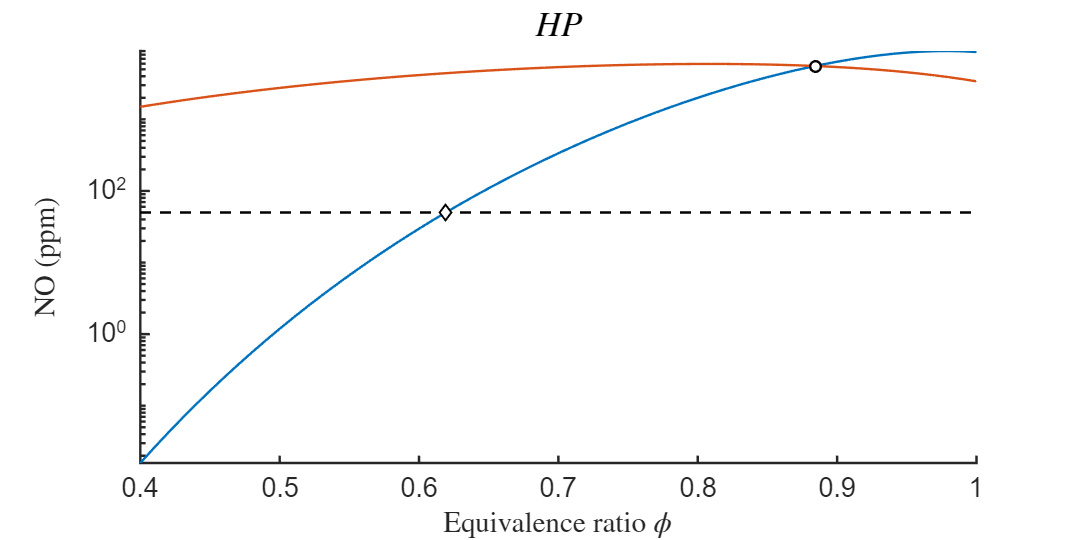

self.Misc.config.labelx = 'Equivalence ratio $\phi$';
self.Misc.config.labely = 'NO (ppm)';
self.Misc.config.tit = strrep(self.PD.ProblemType, '_', ' ');
ax = plot_figure(self.PD.phi.value, X_NO_zeld * 1e6, 'phi', 'X_NO_zeld', self.Misc.config, ...
    self.PD.CompleteOrIncomplete);
ax = plot_figure(self.PD.phi.value, X_NO_eq * 1e6, 'phi', 'X_NO_eq', self.Misc.config, ...
    self.PD.CompleteOrIncomplete, ax);
% Plot critical value and limit line
plot(ax, self.PD.phi.value, line_dashed_y, '--k', 'LineWidth', self.Misc.config.linewidth);
plot(ax, phi_critical, X_NO_critical, 'd', 'LineWidth', self.Misc.config.linewidth, ...
    'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
plot(ax, phi_zeld_eq, X_NO_zeld_eq, 'o', 'LineWidth', self.Misc.config.linewidth, ...
    'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
set(ax,'yscale','log');